E = 1e7;
v = 0.31;
b=0.05; %thickness
a=0.2;
c=0;
P=100;
L=1;

d= (-P*L^3)/(2*E*a^3*b);
w = (3*P*L^2)/(4*E*a^3*b);
% % Computational domain
X0 = 0;
XL = 1;
XComp = [X0 XL];
% 
Y0=-0.2;
YL=0.2;
YComp = [Y0 YL];

syms x1 x2 U1(x1, x2) U2(x1,x2) d_dlUX_dx(x1,x2) d_dlUY_dy(x1,x2) d_dlUX_dy(x1,x2) d_dlUY_dx(x1,x2)
syms dd_dlUX_dxdx(x1,x2) dd_dlUY_dydy(x1,x2) dd_dlUX_dydy(x1,x2) dd_dlUY_dxdx(x1,x2)
syms dd_dlUX_dxdy(x1,x2) dd_dlUX_dydx(x1,x2) dd_dlUY_dydx(x1,x2) dd_dlUY_dxdy(x1,x2)
U1(x1, x2) = (3*P*(x1.^2).*x2-P*x2.^3*(2+v))/(4*E*a^3*b)+(3*P*a^2*x2)/(2*E*a^3*b) - w*x2 + c;
U2(x1, x2) = (-v*3*P*x1.*x2.^2-P*x1.^3)/(4*E*a^3*b) +w*x1 + d;
% U1 = @(x1,x2) (3*P*(x1.^2).*x2-P*x2.^3*(2+v))/(4*E*a^3*b)+(3*P*a^2*x2)/(2*E*a^3*b) - w*x2 + c
% U2 = @(x1,x2) (-v*3*P*x1.*x2.^2-P*x1.^3)/(4*E*a^3*b) +w*x1 + d

$\frac{\partial u_x}{ \partial X}$, $\frac{\partial u_y}{ \partial Y}$, $\frac{\partial u_x}{ \partial Y}$, $\frac{\partial u_y}{ \partial X}$

d_dlUX_dx(x1,x2) =  diff(U1, x1)

$$d\_dlUX\_dx(x1, x2) = \frac{3\,x_{1}\,x_{2}}{80}$$

d_dlUY_dy(x1,x2) = diff(U2, x2)

$$d\_dlUY\_dy(x1, x2) = -\frac{93\,x_{1}\,x_{2}}{8000}$$

d_dlUX_dy(x1,x2) = diff(U1, x2)

$$d\_dlUX\_dy(x1, x2) = \frac{3\,{x_{1}}^{2}}{160}-\frac{693\,{x_{2}}^{2}}{16000}-\frac{69}{4000}$$

d_dlUY_dx(x1,x2) = diff(U2, x1)

$$d\_dlUY\_dx(x1, x2) = -\frac{3\,{x_{1}}^{2}}{160}-\frac{93\,{x_{2}}^{2}}{16000}+\frac{3}{160}$$

$\frac{\partial^2 u_x}{ \partial^2 X}$, $\frac{\partial^2 u_y}{ \partial^2 Y}$, $\frac{\partial^2 u_x}{ \partial^2 Y}$, $\frac{\partial^2 u_y}{ \partial^2 X}$

     dd_dlUX_dxdx(x1,x2) = diff(d_dlUX_dx, x1)

$$dd\_dlUX\_dxdx(x1, x2) = \frac{3\,x_{2}}{80}$$

     dd_dlUY_dydy(x1,x2) = diff(d_dlUY_dy, x2)

$$dd\_dlUY\_dydy(x1, x2) = -\frac{93\,x_{1}}{8000}$$

     dd_dlUX_dydy(x1,x2) = diff(d_dlUX_dy, x2)

$$dd\_dlUX\_dydy(x1, x2) = -\frac{693\,x_{2}}{8000}$$

     dd_dlUY_dxdx(x1,x2) = diff(d_dlUY_dx, x1)

$$dd\_dlUY\_dxdx(x1, x2) = -\frac{3\,x_{1}}{80}$$

$\frac{\partial^2 u_x}{ \partial X \partial Y}$, $\frac{\partial^2 u_x}{ \partial Y \partial X}$,   $\frac{\partial^2 u_y}{ \partial X \partial Y}$, $\frac{\partial^2 u_y}{ \partial Y \partial X}$

     dd_dlUX_dxdy(x1,x2) = diff(d_dlUX_dx, x2)

$$dd\_dlUX\_dxdy(x1, x2) = \frac{3\,x_{1}}{80}$$

     dd_dlUX_dydx(x1,x2) = diff(d_dlUX_dy, x1)

$$dd\_dlUX\_dydx(x1, x2) = \frac{3\,x_{1}}{80}$$

     dd_dlUY_dxdy(x1,x2) = diff(d_dlUY_dx, x2)

$$dd\_dlUY\_dxdy(x1, x2) = -\frac{93\,x_{2}}{8000}$$

     dd_dlUY_dydx(x1,x2) = diff(d_dlUY_dy, x1)

$$dd\_dlUY\_dydx(x1, x2) = -\frac{93\,x_{2}}{8000}$$

$\frac{\partial \sigma _{xx}}{ \partial X}$, $\frac{\partial \sigma _{yy}}{ \partial Y}$, $\frac{\partial \sigma _{xy}}{ \partial Y}$, $\frac{\partial \sigma _{yx}}{ \partial X}$

    d_Sxx_dx = (E/(1-v^2))*(dd_dlUX_dxdx + v*dd_dlUY_dydx)

$$d\_Sxx\_dx(x1, x2) = \frac{80530636799999992257\,x_{2}}{214748364800000}$$

    d_Syy_dy = (E/(1-v^2))*(v*dd_dlUX_dxdy + dd_dlUY_dydy)

$$d\_Syy\_dy(x1, x2) = 0$$

    
    d_Sxy_dy = (E/(2*(1+v)))*(dd_dlUX_dydy + dd_dlUY_dxdy)

$$d\_Sxy\_dy(x1, x2) = -\frac{1610612735999999853\,x_{2}}{4294967296000}$$

    d_Syx_dx = (E/(2*(1+v)))*(dd_dlUX_dydx + dd_dlUY_dxdx)

$$d\_Syx\_dx(x1, x2) = 0$$


$$f=\mathrm{div}\sigma +b$$


    divStress = [d_Sxx_dx + d_Sxy_dy; d_Syy_dy + d_Syx_dx]

$$divStress(x1, x2) = \left(\begin{array}{c} -\frac{393\,x_{2}}{214748364800000}\\ 0 \end{array}\right)$$

    p =  7750; %kg/m3 (steel)
    g = 9.81; %(m/s2)
    b_const = -p*g;
    b = 0;

    % equilibrium eq.
    f = divStress + b

$$f(x1, x2) = \left(\begin{array}{c} -\frac{393\,x_{2}}{214748364800000}\\ 0 \end{array}\right)$$

    test1 = double(subs(f, [x1 x2], [0.2 0.1]))

test1 = 1.0e-12 *

   -0.1830
         0


    test2 = double(subs(f, [x1 x2], [0.1 -0.2]))

test2 = 1.0e-12 *

    0.3660
         0


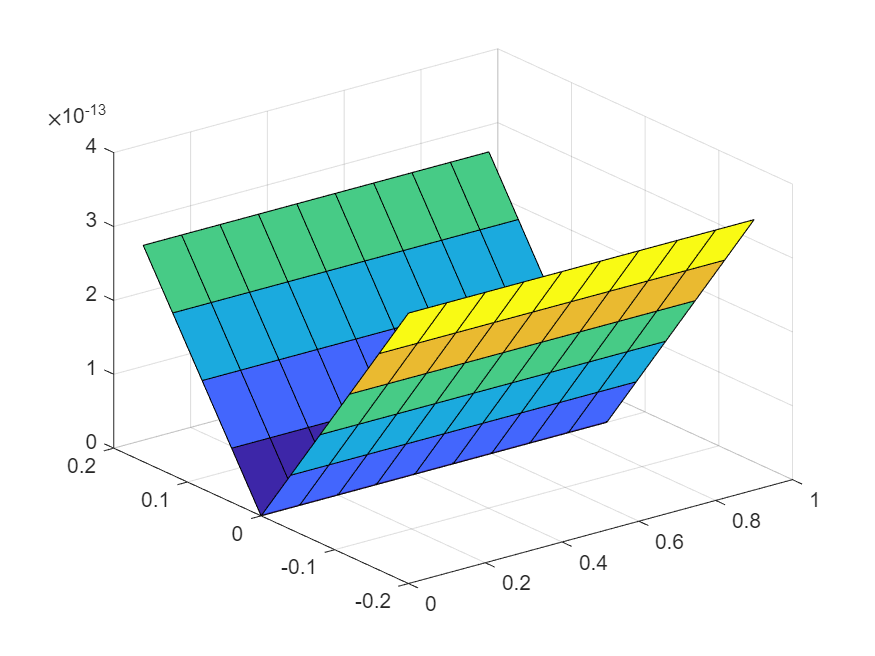


    numPts_x = 10;
    numPts_y = 10;
    err = zeros(numPts_x, numPts_y);
    X = zeros(numPts_x, numPts_y);
    Y = zeros(numPts_x, numPts_y);
    X_curr = X0;
    Y_curr = Y0;
    dX = (XL-X0)/numPts_x;
    dY = (YL-Y0)/numPts_y;
    for ii = 1:numPts_x
        Y_curr = Y0;
        for jj = 1:numPts_y
            err(ii,jj) = norm(double(subs(f, [x1 x2], [X_curr Y_curr])));
            X(ii, jj) = X_curr;
            Y(ii, jj) = Y_curr;
            Y_curr = Y_curr + dY;
        end
        X_curr = X_curr + dX;
    end

    surf(X,Y,err)


%     
%     %surf here!!!
%     %loss f
%     zeroTarget = zeros(size(f), 'like', f);
%     lossF = mse(f, zeroTarget)
% 
%     % Total loss
%     loss = lossF;
% end